# Laboratorio di Automatica (prova del 31 Gennaio 2020)

Riccardo Antonello ([riccardo.antonello@unipd.it](mail:riccardo.antonello@unipd.it)) and Angelo Cenedese ([angelo.cenedese@unipd.it](mail:angelo.cenedese@unipd.it)) 

January 31, 2020

Dept. of Information Engineering, University of Padova

## Esercizio 1

Si consideri un motore elettrico in corrente continua con funzione di trasferimento:


$$P_m(s)\,=\, \frac{Y(s)}{U_a(s)} \,=\, \frac{k_m}{s(T_m s  + 1)}
\qquad\quad\text{con}\qquad\quad
k_m\,=\,5.2\,,\qquad T_m \,=\,0.03$$


da ingresso in tensione di armatura $u_a\;[\mathrm{V}]$ ad uscita in posizione $y\;[\mathrm{rad}]$. Si supponga che la tensione di armatura $u_a$ sia fornita da un driver in tensione con funzione di trasferimento:


$$P_d(s)\,=\, \frac{U_a(s)}{U(s)} \,=\, \frac{1}{T_d s  + 1}
\qquad\text{con}\qquad 
T_d = 10\,\mathrm{ms}$$


da comando in tensione $u\;[\mathrm{V}]$ a tensione di armatura $u_a\;[\mathrm{V}]$. Si desidera progettare un controllore di posizione PID utilizzando il secondo metodo di Ziegler-Nichols (metodo a catena chiusa). A tal scopo, si procede preliminarmente considerando il sistema retroazionato di Fig.1, in cui $P(s)$ rappresenta l'impianto (inteso come connessione in serie del motore e del driver in tensione), mentre $C(s)$ rappresenta un controllore  puramente proporzionale di guadagno $K_P$.

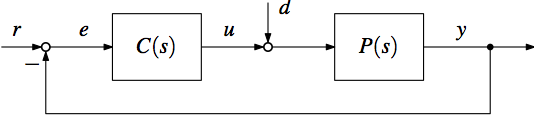

**Figura 1**: Sistema di controllo a retroazione unitaria dall'uscita.

Utilizzando *soltanto* le routines del Control System Toolbox (CST), si svolgano i seguenti punti:

1) Tracciare il luogo delle radici del sistema retroazionato, al variare del guadagno $K_P$ del controllore proporzionale. Determinare poi il valore limite $K_u$ (*ultimate gain*) di guadagno del controllore superato il quale il sistema retroazionato diventa instabile.

*Soluzione.*

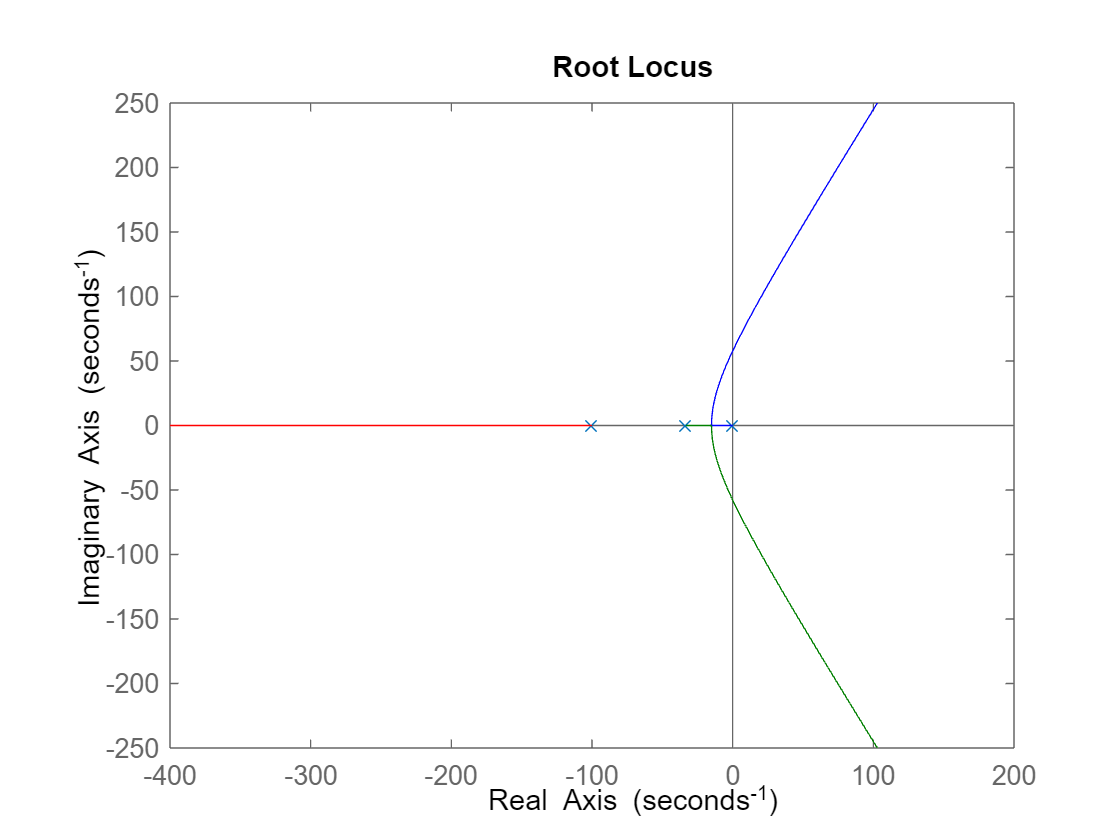

%  define plant tf
Tm = 0.03;
km = 5.2;
Td = 10e-3;
sysP = tf(1, [Td,1]) * tf(km, [Tm, 1, 0]);

%   root locus with proportional controller
figure;
rlocus(sysP);


%   find ultimate gain
ku = margin(sysP)

ku = 25.6410

2) Con il valore di guadagno critico $K_u$ determinato al punto precedente, calcolare la funzione di trasferimento $T(s)$ del sistema in catena chiusa, da riferimento $r$ ad uscita $y$. Mostrare poi la risposta del sistema in catena chiusa ad un riferimento a gradino unitario.

*Soluzione.*

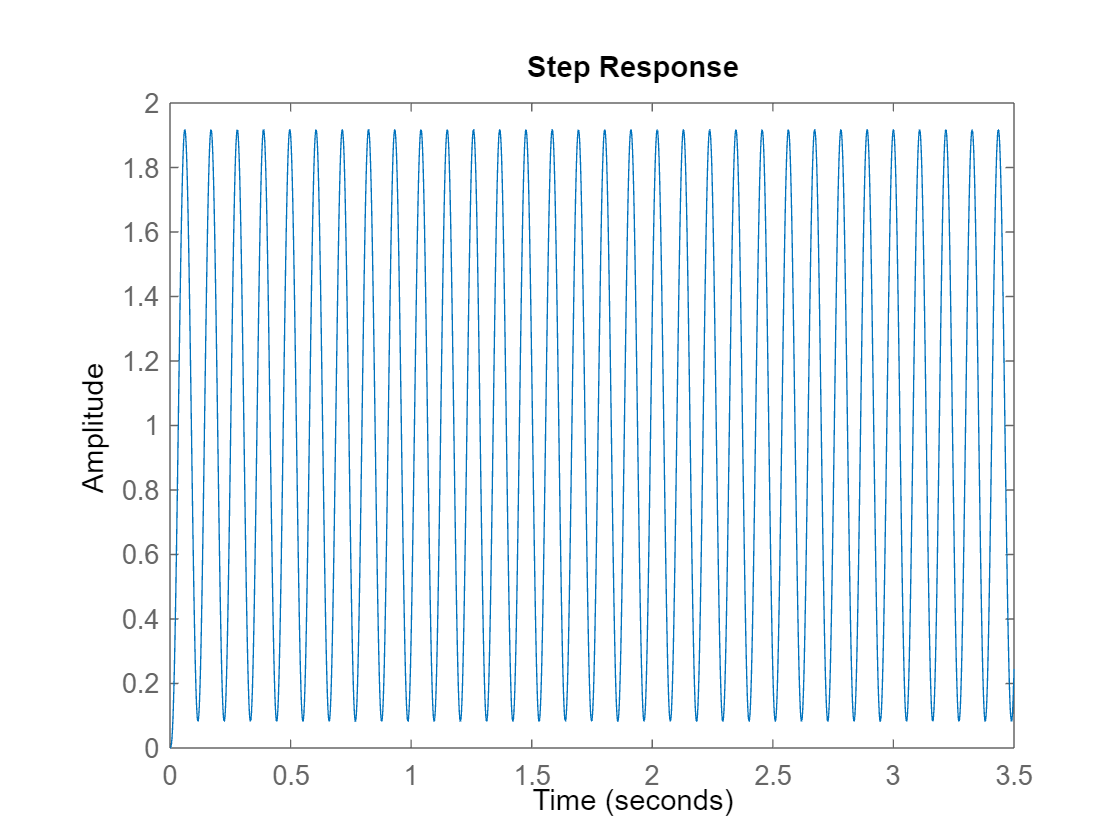

%   proportional controller
sysC = ku;

%   loop tf
sysL = sysC*sysP;

%   closed-loop tf
sysT = feedback(sysL,1);

%   closed-loop step response
figure;
step(sysT);

3) La risposta al gradino determinata al punto precedente presenta una oscillazione persistente. Misurare il periodo $T_u$ di tale oscillazione.

*Soluzione.*

%   period of persistent oscillation
pim = imag( pole(sysT) );
w = max( pim(pim ~= 0) );
Tu = 2*pi/w

Tu = 0.1088

4) Con i valori di guadagno critico $K_u$ e periodo dell'oscillazione persistente $T_u$, utilizzare le formule suggerite dal secondo metodo di Ziegler-Nichols, ovvero:


$$K_P=0.6\,K_u\,,\quad
T_I=0.5\,Tu\,,\quad
T_D=0.125\,Tu$$


per determinare il guadagno proporzionale $K_P$ e i tempi integrale $T_I$ e derivativo $T_D$ del  controllore PID di posizione:


$$C(s)=K_P\left( 
1 + \frac{1}{s T_I} + s T_D
\right)$$


Con il nuovo controllore PID, tracciare il diagramma di Bode della funzione di trasferimento d'anello $L(s)=C(s) P(s)$, e determinare poi la pulsazione di attraversamento $\omega_{gc}$ e il margine di fase $\varphi_m$. 

*Soluzione.*

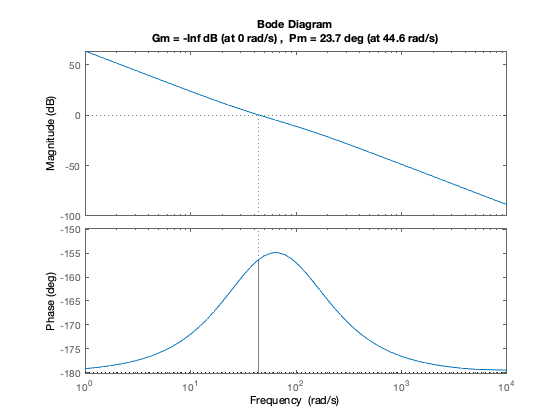

%   PID control design using Ziegler-Nichols method
kp = 0.6*ku;
Ti = 0.5*Tu;
Td = 0.125*Tu;
ki = kp/Ti;
kd = kp*Td;
sysC = tf([kd, kp, ki], [1, 0]);

%   loop tf
sysL = sysP*sysC;

%   stability margins
figure;
margin(sysL);

5) Con il controllore PID di posizione determinato al punto precedente, calcolare la funzione di trasferimento $T(s)$ del sistema in catena chiusa, da riferimento $r$ ad uscita $y$. Valutare successivamente la risposta $y$ del sistema in catena chiusa ad un riferimento di posizione $r$ a gradino unitario, e mostrarla poi in una figura MATLAB. Si determinino inoltre tempo di assestamento al $5\%$ e sovraelongazione percentuale.

*Soluzione.*

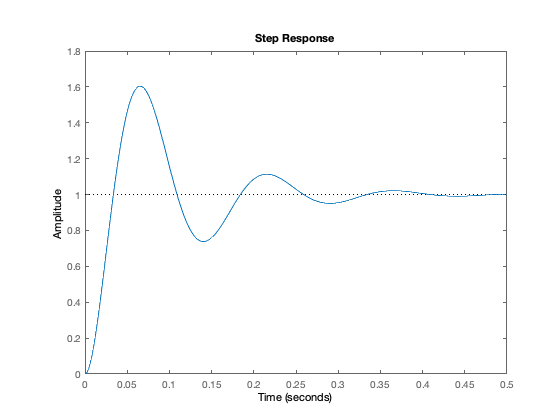

%   closed-loop tf
sysT = feedback(sysL,1);

%   closed-loop step response
figure;
step(sysT);


%   step response parameters
stepinfo(sysT, 'SettlingTimeThreshold', 0.05)

ans = struct with fields:
        RiseTime: 0.0228
    SettlingTime: 0.2442
     SettlingMin: 0.7383
     SettlingMax: 1.6040
       Overshoot: 60.4001
      Undershoot: 0
            Peak: 1.6040
        PeakTime: 0.0655
